## 第一部分 方程形式

第一边值问题的双曲方程如下:


$$\left\lbrace \begin{array}{ll}
D_t^2 u-c^2 D_x^2 u=f\left(x,t\right), & \left(x,t\right)\in \left(0,L\right)\times \left(0,T\right)\\
u\left(x,0\right)=\varphi_1 \left(x\right),D_t u\left(x,0\right)=\varphi_2 \left(x\right), & x\in \left\lbrack 0,L\right\rbrack ,\\
u\left(0,t\right)=\psi_1 \left(t\right),u\left(L,t\right)=\psi_2 \left(t\right), & t\in \left\lbrack 0,T\right\rbrack \ldotp 
\end{array}\right.\left(1\right)$$


## 第二部分 数值计算

数值算例方程为


$$\left\lbrace \begin{array}{ll}
D_t^2 u-D_x^2 u=\left(t^2 -x^2 \right)\sin \left(\textrm{xt}\right), & \left(x,t\right)\in \left(0,1\right)\times \left(0,1\right)\\
u\left(x,0\right)=0,D_t u\left(x,0\right)=x, & x\in \left\lbrack 0,1\right\rbrack ,\\
u\left(0,t\right)=0,u\left(L,t\right)=\sin \left(t\right), & t\in \left\lbrack 0,1\right\rbrack \ldotp 
\end{array}\right.$$


方程的唯一光滑精确解为$u\left(x,t\right)=\sin \left(\textrm{xt}\right)$.

## 1 显式差分格式计算

显式格式的差分方程为


$$\left\lbrace \begin{array}{ll}
\delta_t^2 u_j^k -c^2 \delta_x^2 u_j^k =f\left(x_j ,t_k \right), & j=1:J-1,k=1:K-1,\\
2\tau^{-1} \left(\delta_t u_j^{\frac{1}{2}} -\varphi_2 \left(x_j \right)\right)-c^2 \delta_x^2 u_j^0 =f\left(x_j ,t_0 \right), & j=1:J-1,\\
u_j^0 =\varphi_1 \left(x_j \right), & j=1:J-1,\\
u_0^k =\psi_1 \left(t_k \right),u_J^k =\psi_2 \left(t_k \right), & k=0:K\ldotp 
\end{array}\left(2\right)\right.$$


在方程$(2)$中定义$r=c^{2}\tau^{2}h^{-2}$,方程$(2)$实际的迭代格式是


$$\left\lbrace \begin{array}{ll}
u_j^0 =\varphi_1 \left(x_j \right),u_j^1 =u_j^0 +\tau \psi \left(x_j \right)+\frac{1}{2}\tau^2 \left(c^2 \delta_x^2 u_j^0 +f\left(x_j ,t_0 \right)\right), & j=1:J-1,\\
u_0^k =\psi_1 \left(t_k \right),u_J^k =\psi_2 \left(t_k \right), & k=0:K,\\
u_j^{k+1} =ru_{j-1}^k +2\left(1-r\right)u_j^k +ru_{j+1}^k -u_j^{k-1} +\tau^2 f\left(x_j ,t_k \right), & j=1:J-1,k=1:K-1,
\end{array}\right.\left(3\right)$$


#### 步骤一 参数赋予

clear
%f是非齐次项
f=@(x,t)((t.^2-x.^2)*sin(x*t));
%边界条件函数
varphi_1=@(x)(0);
varphi_2=@(x)(x);
psi_1=@(t)(0);
psi_2=@(t)(sin(t));
%u_ES是精确解函数
u_ES=@(x,t)(sin(x*t));
%迭代步数定义
J=20;
K=10;
%计算区间端点和长度定义
a1=0;
b1=1;
a2=0;
b2=1;
L1=(b1-a1);
L2=(b2-a2);
%均匀步长h1,h2定义
h=(L1/J);
tau=(L2/K);
c=1;
r=(c^2)*(h^2)*(tau^(-2));
%u是数值解储存矩阵,u_ESM是精确解储存矩阵
u=zeros(J+1,K+1);
u_ESM=zeros(J+1,K+1);
%C++风格数组转换函数
j_=@(x)(x+1);
k_=@(x)(x+1);
%算子函数定义
delta_x2=@(u,j,k)((u(j-1,k)-2*u(j-1,k)+u(j-1,k))/(h^2));

#### 步骤二 初值赋予

for j_c=0:J
    j=j_c+1;
    u(j,k_(0))=varphi_1(j_c*h);
end

for j_c=1:J-1
    j=j_c+1;
    u(j,k_(1))=u(j,k_(0))+tau*varphi_2(j_c*h)...
            +(1/2)*(tau^(2))*(c^2*delta_x2(u,j,k_(0)+f(j_c*h,0)));
end

for k_c=0:K
    k=k_c+1;
    u(j_(0),k)=psi_1(k_c*tau);
    u(j_(J),k)=psi_2(k_c*tau);
end

#### 步骤三 迭代计算

for k_c=1:K-1
    k=k_c+1;
    for j_c=1:J-1
        j=j_c+1;
        u(j,k+1)=r*u(j-1,k)+2*(1-r)*u(j,k)+r*u(j+1,k)...
        -u(j,k-1)+(tau^2)*f(j_c*h,k_c*tau);
    end
end

for k_c=0:K
    k=k_c+1;
    for j_c=0:J
        j=j_c+1;
        u_ESM(j,k)=u_ES(j_c*h,k_c*tau);
    end
end

#### 计算结果绘图

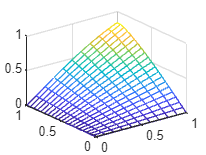

mesh(tau*(0:K),h*(0:J),u)

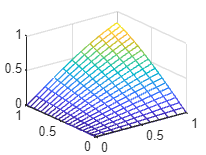

mesh(tau*(0:K),h*(0:J),u_ESM)

#### 显示最大误差

disp(max(max(abs(u-u_ESM))))

    0.0367



### 2.隐式差分格式计算

隐式格式的差分方程为


$$\left\lbrace \begin{array}{ll}
\delta_t^2 u_j^k -\frac{1}{2}c^2 \left(\delta_x^2 u_j^{k-1} +\delta_x^2 u_j^{k+1} \right)=f\left(x_j ,t_k \right), & j=1:J-1,k=1:K-1,\\
2\tau^{-1} \left(\delta_t u_j^{\frac{1}{2}} -\varphi_2 \left(x_j \right)\right)-c^2 \delta_x^2 u_j^{\frac{1}{2}} =f\left(x_j ,t_0 \right), & j=1:J-1,\\
u_j^0 =\varphi_1 \left(x_j \right), & j=1:J-1,\\
u_0^k =\psi_1 \left(t_k \right),u_J^k =\psi_2 \left(t_k \right), & k=0:K\ldotp 
\end{array}\left(4\right)\right.$$


在方程$(4)$中定义$r=c^{2}\tau^{2}h^{-2}$,方程$(4)$实际的迭代格式是


$$\left\lbrace \begin{array}{ll}
u_j^0 =\varphi_1 \left(x_j \right),u_j^1 =u_j^0 +\tau \psi \left(x_j \right)+\frac{1}{2}\tau^2 f\left(x_j ,t_0 \right), & j=1:J-1,\\
u_0^k =\psi_1 \left(t_k \right),u_J^k =\psi_2 \left(t_k \right), & k=0:K,\\
u_j^{k+1} =ru_{j-1}^k +2\left(1-r\right)u_j^k +ru_{j+1}^k -u_j^{k-1} +\tau^2 f\left(x_j ,t_k \right), & j=1:J-1,k=1:K-1,
\end{array}\left(5\right)\right.$$


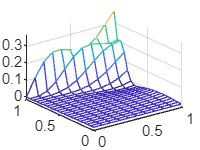

clear
%f是非齐次项
f=@(x,t)((t.^2-x.^2)*sin(x*t));
%边界条件函数
varphi_1=@(x)(0);
varphi_2=@(x)(x);
psi_1=@(t)(0);
psi_2=@(t)(sin(t));
%u_ES是精确解函数
u_ES=@(x,t)(sin(x*t));
%迭代步数定义
J=20;
K=10;
%计算区间端点和长度定义
a1=0;
b1=1;
a2=0;
b2=1;
L1=(b1-a1);
L2=(b2-a2);
%均匀步长h1,h2定义
h=(L1/J);
tau=(L2/K);
c=1;
r=(c^2)*(h^2)*(tau^(-2));
%u是数值解储存矩阵,u_ESM是精确解储存矩阵
u=zeros(J+1,K+1);
f_after=zeros(J+1,K+1);
u_ESM=zeros(J+1,K+1);
%C++风格数组转换函数
j_=@(x)(x+1);
k_=@(x)(x+1);
%算子函数定义
delta_x2=@(u,j,k)((u(j-1,k)-2*u(j-1,k)+u(j-1,k))/(h^2));
for j_c=0:J
    j=j_c+1;
    u(j,k_(0))=varphi_1(j_c*h);
end

for j_c=1:J-1
    j=j_c+1;
    u(j,k_(1))=(1/2)*r*delta_x2(u,j,k_(0))-u(j,k_(0))...
            +(1/2)*(tau^(2))*(f(j_c*h,0));
end

for k_c=0:K
    k=k_c+1;
    for j_c=0:J
        j=j_c+1;
        f_after(j,k)=f(j_c*h,k_c*tau);
    end
end
for k_c=0:K
    k=k_c+1;
    u(j_(0),k)=psi_1(k_c*tau);
    u(j_(J),k)=psi_2(k_c*tau);
end
e = r*ones(J+1,1);
A=spdiags([-e/2,1+e,-e/2],[-1,0,1],J+1,J+1);
temp=zeros(J+1,K+1);
for k_c=0:K
    k=k_c+1;
    temp(1,k)=r/2*psi_1(k_c*tau);
    temp(end,k)=r/2*psi_2(k_c*tau);
end
for k_c=1:K-1
    k=k_c+1;
    u(:,k+1)=A\(-A*u(:,k-1)+2*u(:,k)+(tau^2)*f_after(:,k) ...
        +temp(:,k+1));
end
for k_c=0:K
    k=k_c+1;
    for j_c=0:J
        j=j_c+1;
        u_ESM(j,k)=u_ES(j_c*h,k_c*tau);
    end
end
mesh(tau*(0:K),h*(0:J),u)

disp(max(max(abs((u(2:J-2,2:K-2)-u_ESM(2:J-2,2:K-2))))))

    0.5362

